fn = "C:\Users\noahr\Documents\GitHub\ntp\Saved_Data\trial_data_MFCC_100_162300.csv"

fn = "C:\Users\noahr\Documents\GitHub\ntp\Saved_Data\trial_data_MFCC_100_162300.csv"

data = readtable(fn);

data.Var1 = [];
initial_time = data.Time(1);
data.ElapsedTime = data.Time - initial_time;
data.FilteredMassFlow = filter(ones(1,8)*0.125,1,data.MassFlow);

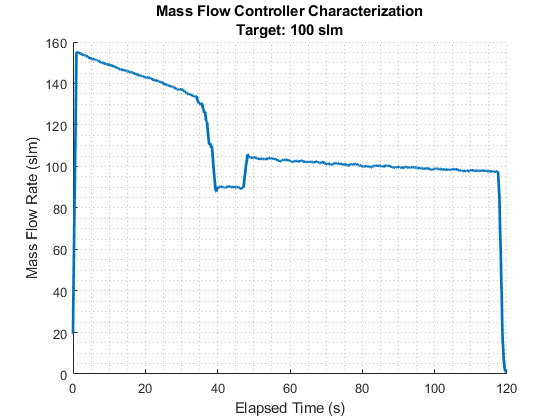

figure;
hold on

% plot(data.ElapsedTime,data.MassFlow)
plot(data.ElapsedTime,data.FilteredMassFlow,'LineWidth',2)
grid minor
ylabel('Mass Flow Rate (slm)')
xlabel('Elapsed Time (s)')
title(["Mass Flow Controller Characterization","Target: 100 slm"])